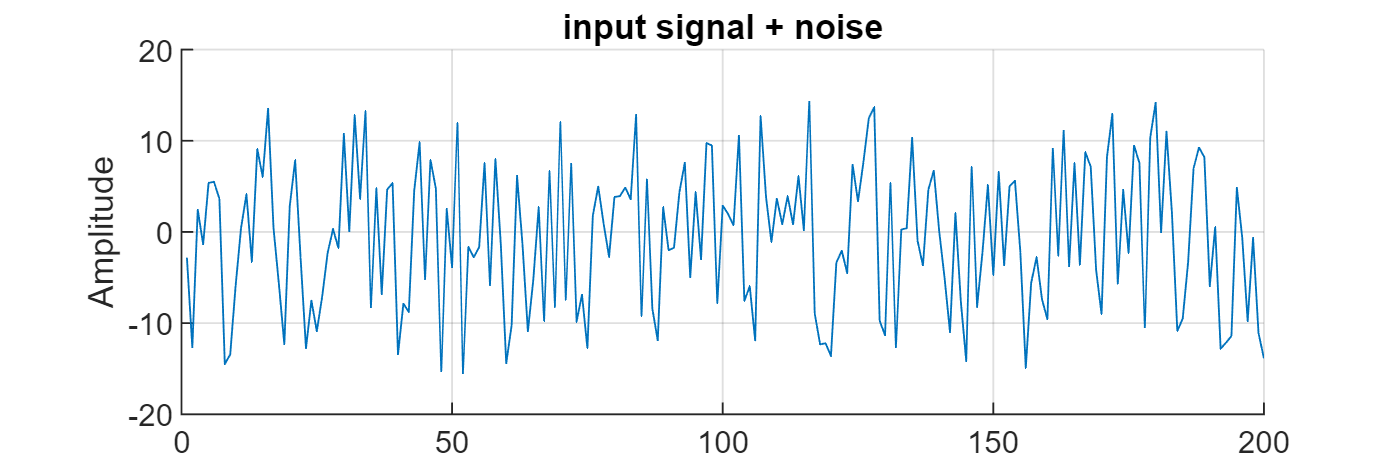

clc;
clear;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TASK 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%part 1
figure('Position',[0 0 1500 500])
hold on
n=1:200; 
N = length(n);
phase = 0;
x = cos((pi/15).*N+phase);

%part 2
noisevals = 30*(rand(N,1)-0.5);
y=x+noisevals;

plot(n,y)
title('input signal + noise')
grid on
ylabel('Amplitude')
hold off

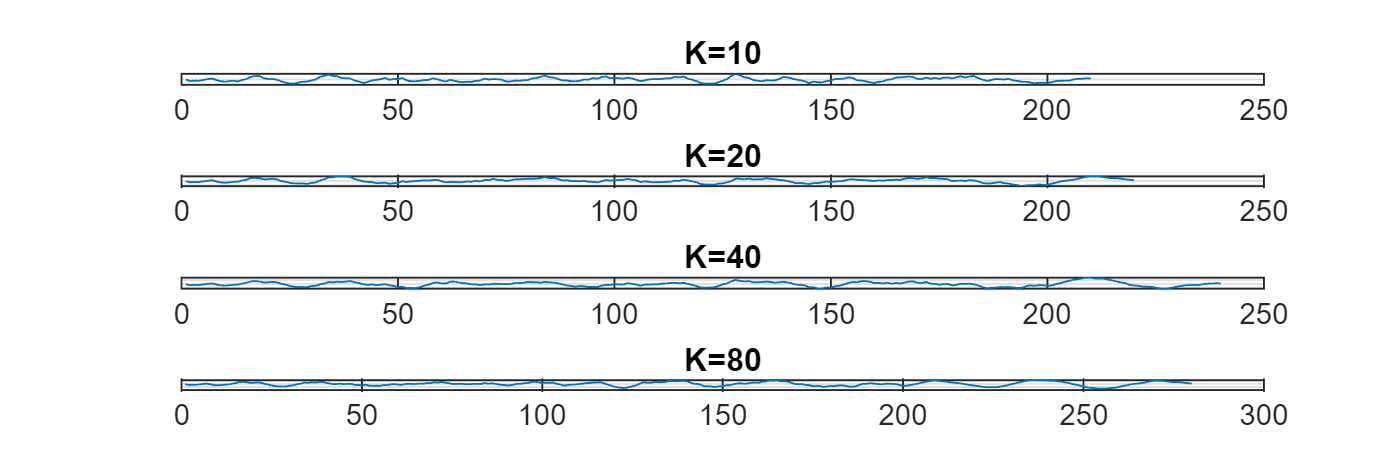


figure('Position',[0 0 1500 500])
hold on
subplot(4,1,1)
%part 3 and 4
K=10; %20,30,40
m=0:K;
h_n0 = cos((pi/15).*m+phase);
rxh=conv(fliplr(y),h_n0);
plot(rxh)
grid on
title('K=10')

subplot(4,1,2)
K=20; %20,40,80
m=0:K;
h_n1 = cos((pi/15).*m+phase);
rxh=conv(fliplr(y),h_n1);
plot(rxh)
grid on
title('K=20')

subplot(4,1,3)
K=40;
m=0:K;
h_n2 = cos((pi/15).*m+phase);
rxh=conv(fliplr(y),h_n2);
plot(rxh)
grid on
title('K=40')

subplot(4,1,4)
K=80;
m=0:K;
h_n3 = cos((pi/15).*m+phase);
rxh=conv(fliplr(y),h_n3);
plot(rxh)
grid on
title('K=80')
hold off

%more accurate with higher k value

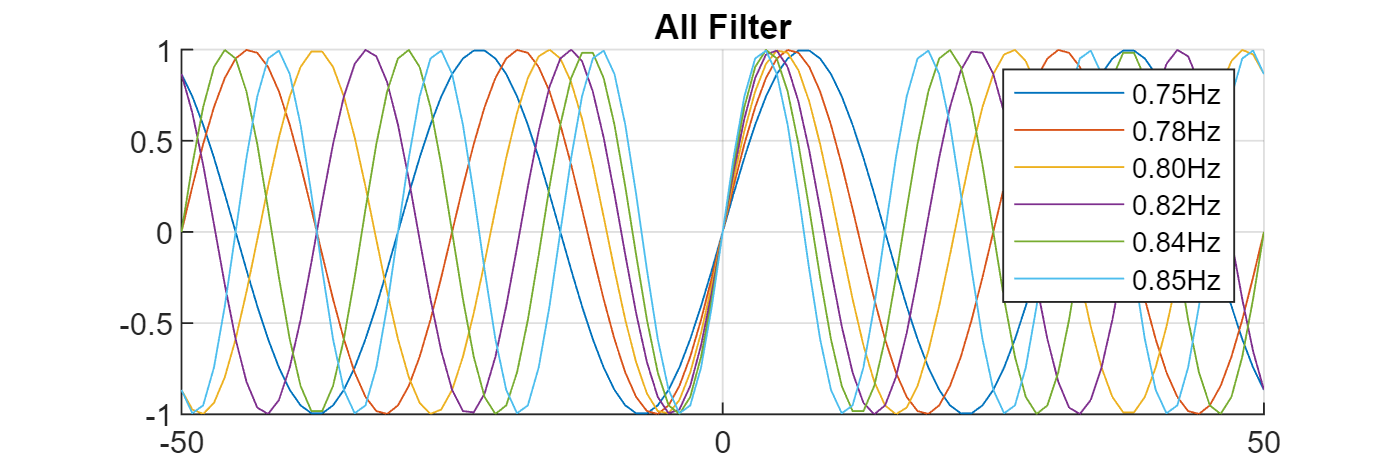

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%TASK 2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%part 1
n1=-50:50;
T=1/30;
%1hz to 2hz
%rand+1
phase1=0;
h_n2_1 = sin(pi*2*1.0*n1.*(T));
h_n2_2 = sin(pi*2*1.2*n1.*(T));
h_n2_3 = sin(pi*2*1.4*n1.*(T));
h_n2_4 = sin(pi*2*1.6*n1.*(T));
h_n2_5 = sin(pi*2*1.8*n1.*(T));
h_n2_6 = sin(pi*2*2.0*n1.*(T));

figure('Position',[0 0 1500 500])
hold on
%subplot(6,1,1);
plot(n1,h_n2_1,'DisplayName', '0.75Hz');
plot(n1,h_n2_2,'DisplayName', '0.78Hz');
plot(n1,h_n2_3,'DisplayName', '0.80Hz');
plot(n1,h_n2_4,'DisplayName', '0.82Hz');
plot(n1,h_n2_5,'DisplayName', '0.84Hz');
plot(n1,h_n2_6,'DisplayName', '0.85Hz');
title('All Filter')
grid on
hold off
red_pixel_val = importdata("red_pixel_values.mat");
legend;

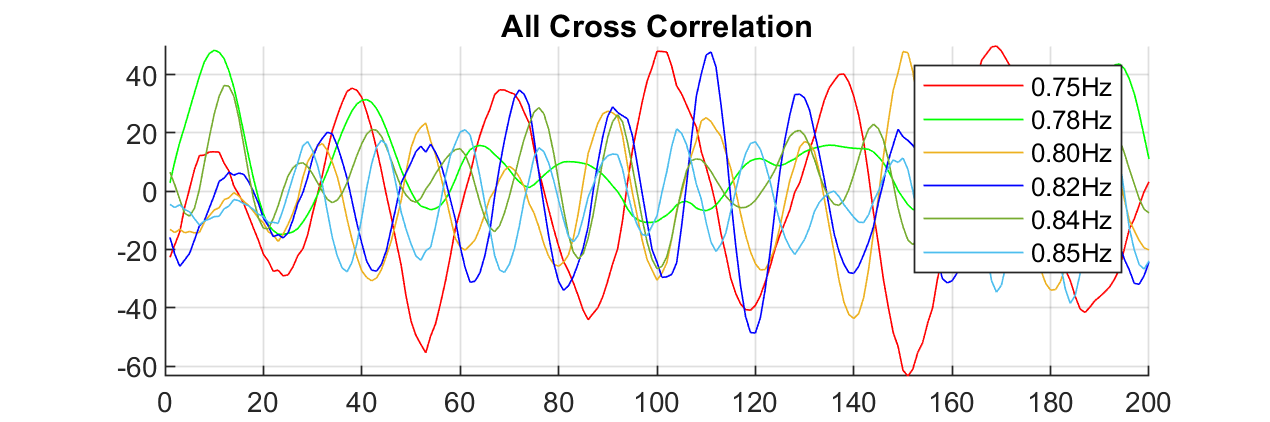


%part 2
figure('Position',[0 0 1500 500])
hold on
plot(conv(red_pixel_val,fliplr(h_n2_1),"valid"),'red', 'DisplayName', '0.75Hz');
plot(conv(red_pixel_val,fliplr(h_n2_2),"valid"),'green', 'DisplayName', '0.78Hz' );
plot(conv(red_pixel_val,fliplr(h_n2_3),"valid"), 'DisplayName', '0.80Hz');
plot(conv(red_pixel_val,fliplr(h_n2_4),"valid"),'blue', 'DisplayName', '0.82Hz');
plot(conv(red_pixel_val,fliplr(h_n2_5),"valid"), 'DisplayName', '0.84Hz');
plot(conv(red_pixel_val,fliplr(h_n2_6),"valid"), 'DisplayName', '0.85Hz');
title('All Cross Correlation')
legend
grid on
hold off

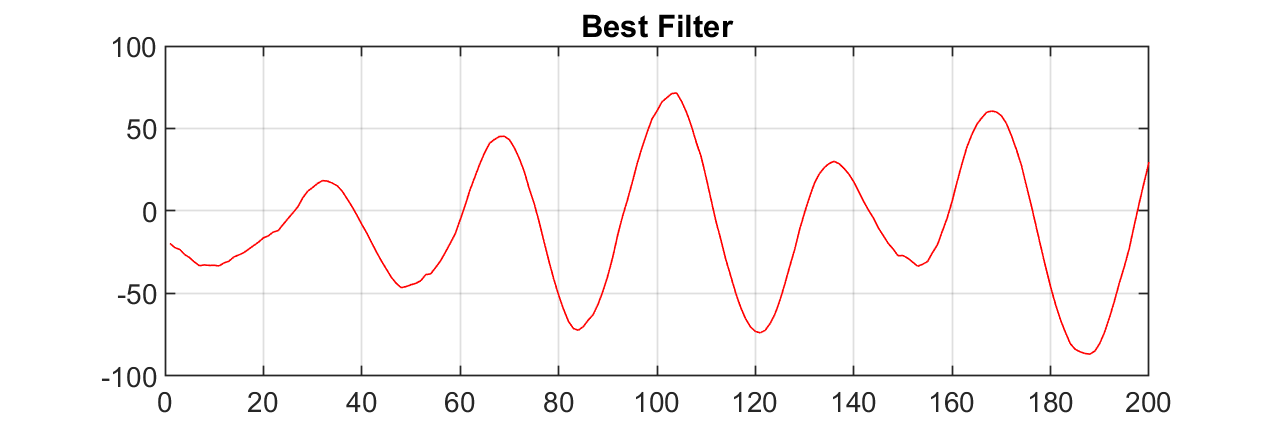


%Best filter is 0.82 due to the higher peaks and lower peaks
%Commented Code below is how I found the best filter
%Finding best value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%for i=0.80:0.01:1
%h = sin(pi*2*i*n1.*(T));
%max(h)
%i
%end
%Throw out the max of 1s, leaves 0.92, 0.83
%started at 0.7 and all values too low
h_n = sin(pi*2*0.83*n1.*(1/30));
figure('Position',[0 0 1500 500])
plot(conv(red_pixel_val,fliplr(h_n),"valid"),'red', 'DisplayName', '0.92Hz');
title('Best Filter')
grid on

%finding min and max
h_n3_1 = conv(red_pixel_val,fliplr(h_n),"valid");
[x,y] = max(h_n3_1)

x = 71.5293

y = 104

[x,y] = min(h_n3_1)

x = -86.7657

y = 188

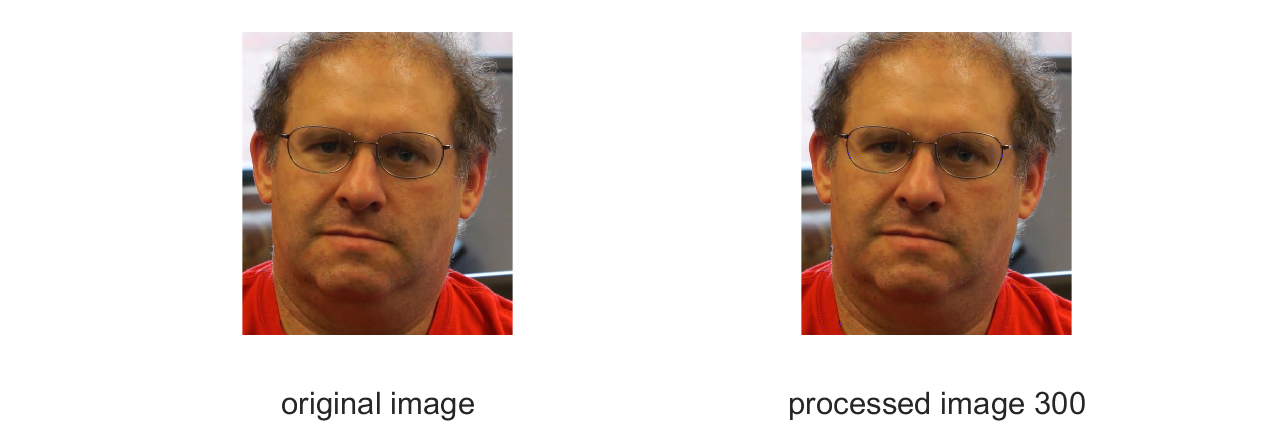

video=load('rgb_video_values.mat');

% downsample the video images for debugging and testing by a factor of (downsample_by_M)
% IMPORTANT: Set downsample_by_M = 1 for your final project results.
downsample_by_M = 5;
if (downsample_by_M > 5) 
    rgb_images = reshape(video.imageStack_uint8,[video.rows,video.cols,3,video.num_frames]);
    rgb_small = rgb_images(1:downsample_by_M:video.rows,1:downsample_by_M:video.cols,:);
    video.cols = floor((video.cols+1)/downsample_by_M);
    video.rows = floor((video.rows+1)/downsample_by_M);
    video.imageStack_uint8 = reshape(rgb_small,[video.rows*video.cols*3,video.num_frames]);
end

x_of_n = video.imageStack_uint8;

% REPLACE CODE HERE TO SET THE VALUE OF y_of_n and set your own alpha value
n1=-50:50;
h_n = sin(pi*2*0.83*n1.*(1/30));
alpha = 3;
y_of_n = conv2(x_of_n,fliplr(h_n), "same");
%end of my code

rgb_images = reshape(x_of_n,[video.rows,video.cols,3,video.num_frames]);
rgb_processed = reshape(y_of_n,[video.rows,video.cols,3,video.num_frames]);
new_rgb_images = rgb_images + uint8(alpha*rgb_processed);
for frame=1:video.num_frames
    figure(1), subplot(1,2,1), imshow(rgb_images(:,:,:,frame),'InitialMagnification', 'fit'), xlabel('original image');
    framestr = sprintf('processed image %d',frame);
    figure(1), subplot(1,2,2), imshow(new_rgb_images(:,:,:,frame),'InitialMagnification', 'fit'), xlabel(framestr);
    pause(1/30);
end

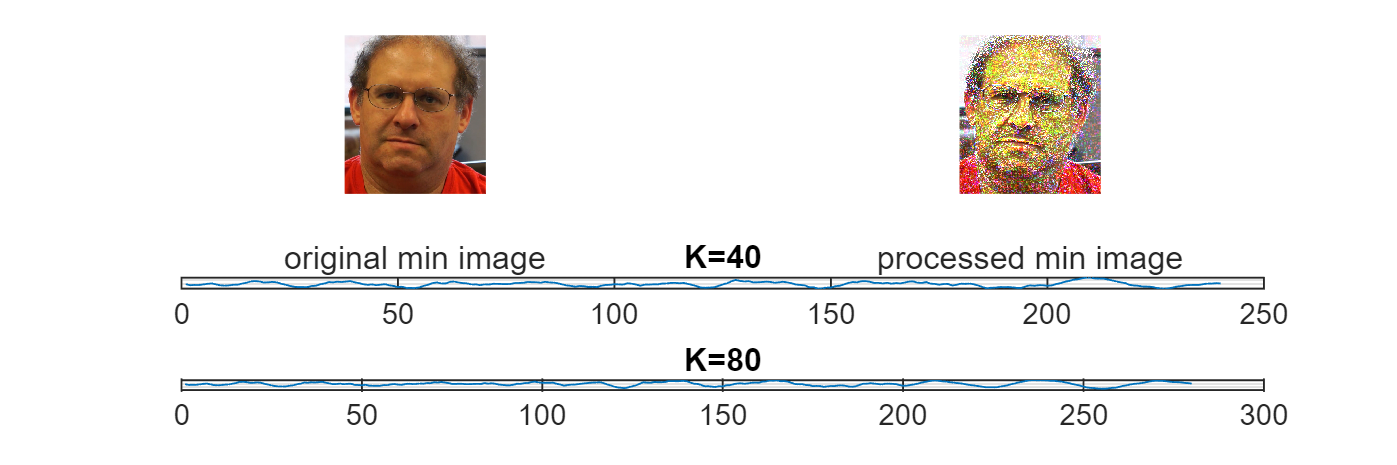


minframe = 188;
maxframe = 104;
figure(2), subplot(2,2,1), imshow(rgb_images(:,:,:,minframe)), xlabel('original min image');
figure(2), subplot(2,2,2), imshow(new_rgb_images(:,:,:,minframe)), xlabel('processed min image');

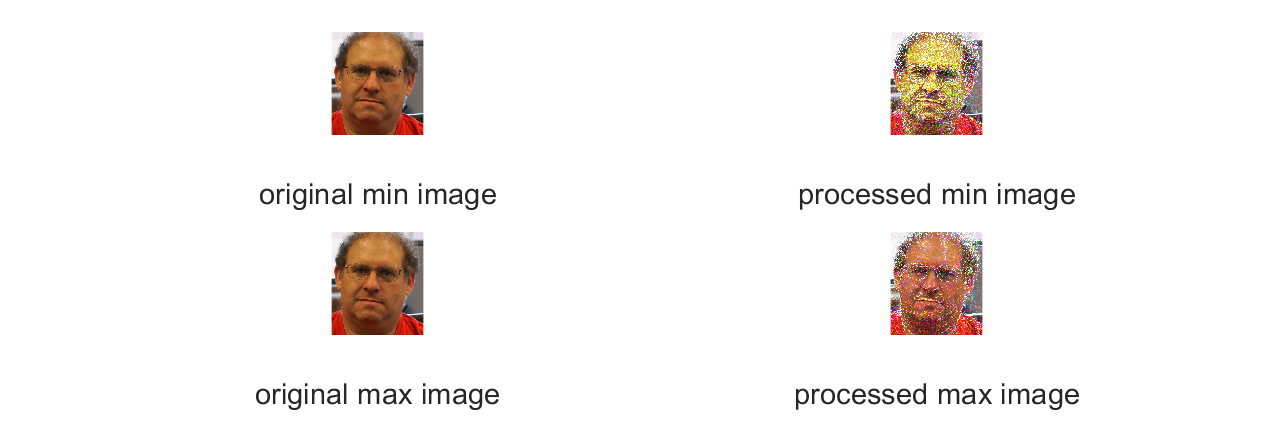

figure(2), subplot(2,2,3), imshow(rgb_images(:,:,:,maxframe)), xlabel('original max image');
figure(2), subplot(2,2,4), imshow(new_rgb_images(:,:,:,maxframe)), xlabel('processed max image');